% Load Dataset
data = readmatrix('SquareBack_NW_0_0yaw_Y=0m_FlowField_Instantaneous.csv');

% Extract x,y,z data
x = data(:,1);
y = data(:,2);
z = data(:,3);

% data at y=0

y_target = 0.0;
tol = 1e-3;
idx = abs(y - y_target) < tol;

x_slice = x(idx);
z_slice = z(idx);


% Building snapshot matrix

snapshot = [];
snapshot(:,1)=data(:,4);

for i = 1:499
    col_idx = 4 + 3*i;      % adjust if needed
    snapshot(:, i+1) = data(:, col_idx);
end

snapshot_data=snapshot(:,16);
num_zeros = sum(snapshot_data == 0);
disp(num_zeros)

    17



% Data Preprocessing 

invalid_mask = (snapshot == -9999) | isnan(snapshot);
fully_invalid_rows = all(invalid_mask, 2);   % only remove rows where all values are invalid
snapshot_clean = snapshot(~fully_invalid_rows, :);
x_slice = x_slice(~fully_invalid_rows);
z_slice = z_slice(~fully_invalid_rows);
snapshot_clean(snapshot_clean == -9999) = 0;
snapshot_clean(isnan(snapshot_clean)) = 0;

[n_rows, n_cols] = size(snapshot_clean);

for j = 1:n_cols
    col = snapshot_clean(:,j);
    
    % Find valid indices: not -9999, not NaN, not 0
    valid = (col ~= -9999) & ~isnan(col) & (col ~= 0);
    x = 1:n_rows;
    
    % Interpolate missing data (linear + extrapolation)
    col(~valid) = interp1(x(valid), col(valid), x(~valid), 'linear', 'extrap');
    
    % Save back
    snapshot_clean(:,j) = col;
end


snapshot_data=snapshot_clean(:,16);
num_zeros = sum(snapshot_data == 0);
disp(num_zeros);

     0




fprintf('Snapshot cleaning complete. Removed %d fully invalid rows.\n', sum(fully_invalid_rows));

Snapshot cleaning complete. Removed 6319 fully invalid rows.


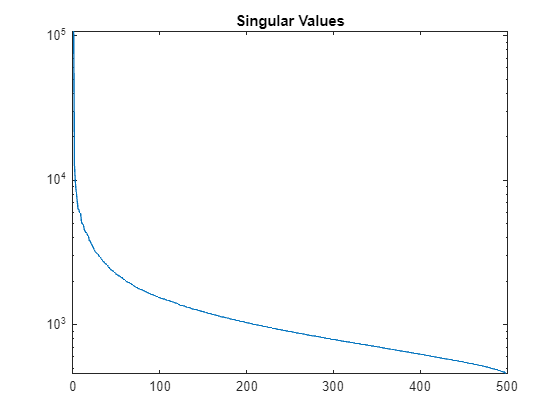

% SVD
X=snapshot_clean(:,1:499);
Y=snapshot_clean(:,2:500);

[U,S,V]=svd(X,"econ");

figure;
semilogy(diag(S));
title("Singular Values")

% Choosing r that gives eig values close to 1

s = diag(S);
energy = cumsum(s.^2) / sum(s.^2);
r = find(energy > 0.99, 1)

r = 233

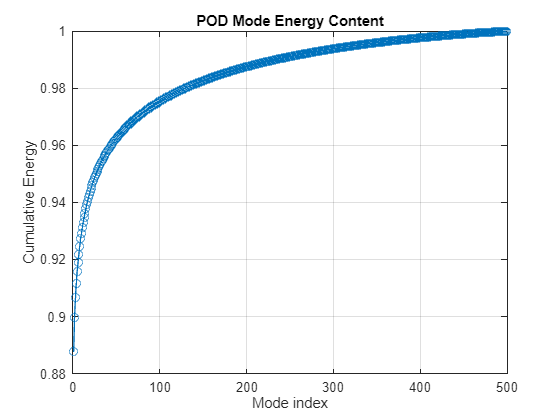

figure;
plot(energy, 'o-');
xlabel('Mode index');
ylabel('Cumulative Energy');
title('POD Mode Energy Content');
grid on;


% r=60;
U_r=U(:,1:r);
S_r=S(1:r,1:r);
V_r=V(:,1:r);

A_red= U_r'*Y*V_r/S_r;

[W,D]=eig(A_red);
lambda=diag(D);

% Reconstructed Matrix

Phi =Y*V_r/S_r*W;

x_1=X(:,1);

disp(min(x_1));

  -25.8000



disp(max(x_1));

   47.4600



b=Phi\x_1;
% disp(unique(b));
disp(rank(X));

   499




time_dynamics = zeros(r, size(X,2));
for t = 1:size(X,2)
    time_dynamics(:,t) = (b .* (lambda.^(t-1)));
end

X_dmd = Phi * time_dynamics;

disp(size(X_dmd));

       66201         499



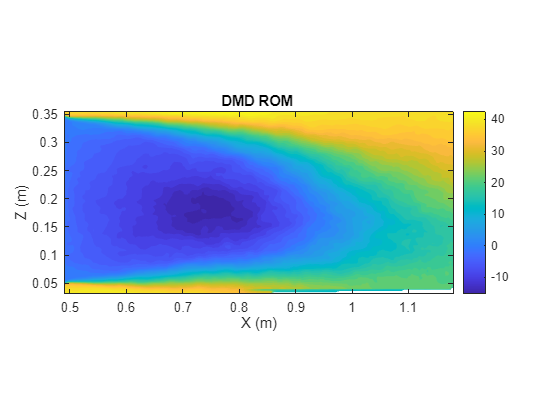


xq = linspace(min(x_slice), max(x_slice), 150);
zq = linspace(min(z_slice), max(z_slice), 150);
[Xq, Zq] = meshgrid(xq, zq);


X_dmd=real(X_dmd);
Vq = griddata(x_slice, z_slice, X_dmd(:,5), Xq, Zq, 'natural');

%% Plot contour
figure;
contourf(Xq, Zq, Vq, 40, 'LineStyle', 'none');
colorbar;
xlabel('X (m)');
ylabel('Z (m)');
title('DMD ROM ');
axis equal tight;

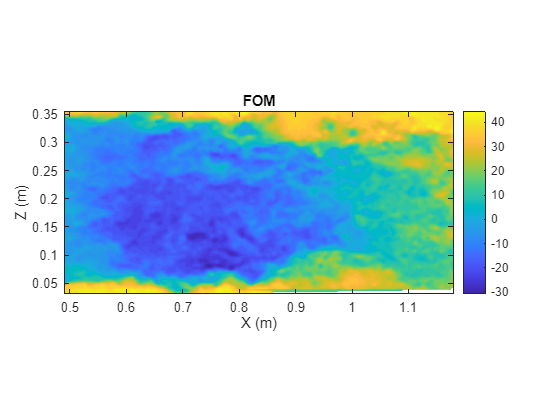

% U Velocity Contour at Y = 0
Oq = griddata(x_slice, z_slice, snapshot_clean(:,10), Xq, Zq, 'natural');

%% Plot contour
figure;
contourf(Xq, Zq, Oq, 40, 'LineStyle', 'none');
colorbar;
xlabel('X (m)');
ylabel('Z (m)');
title('FOM');
axis equal tight;

snapshot_data=snapshot_clean(:,16);
num_zeros = sum(snapshot_data == 0);
disp(num_zeros);

     0




% Overall Errors
X_original=X;
error_mse = mean((X_dmd(:) - X_original(:)).^2);
error_rel = norm(X_dmd - X_original, 'fro') / norm(X_original, 'fro');

fprintf('MSE = %.4e\n', error_mse);

MSE = 5.0939e+01


fprintf('Relative error = %.4f%%\n', error_rel*100);

Relative error = 35.9428%


disp(rank(X_original));

   499



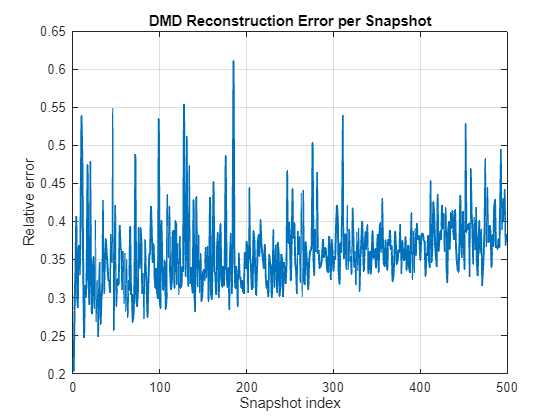

%Per Snapshot
snapshot_error = vecnorm(X_dmd - X_original) ./ vecnorm(X_original);
figure;
plot(snapshot_error, 'LineWidth', 1.5);
xlabel('Snapshot index');
ylabel('Relative error');
title('DMD Reconstruction Error per Snapshot');
grid on;

display(snapshot_error(1:10))

    0.2029    0.2829    0.3340    0.4061    0.3005    0.2870    0.3679    0.3301    0.4069    0.5383



mask_valid = X_original ~= -9999 & ~isnan(X_original);
error_rel = norm(X_dmd(mask_valid) - X_original(mask_valid), 'fro') / ...
            norm(X_original(mask_valid), 'fro');
fprintf('Relative error (valid points only) = %.2f%%\n', error_rel*100);

Relative error (valid points only) = 35.94%


threshold = 1e-3;
mask = abs(X_original) > threshold;
error_rel = norm(X_dmd(mask) - X_original(mask), 'fro') / norm(X_original(mask), 'fro');
disp(error_rel);

    0.3594



% filename = 'X_dmd_reconstructed03.csv';
% 
% % Save matrix
% writematrix(X_dmd, filename);
% 
% fprintf('X_dmd2 saved to %s\n', filename);

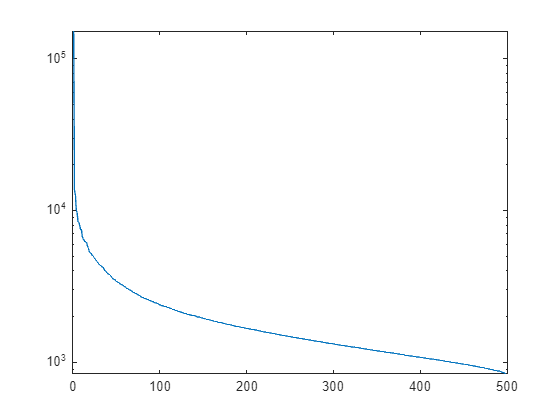

% TLS DMD % 

X1=X;
X2=Y;
Z = [X1; X2]; 

% Compute SVD of stacked matrix
[Uz,Sz,Vz] = svd(Z,'econ');

figure;
semilogy(diag(Sz));

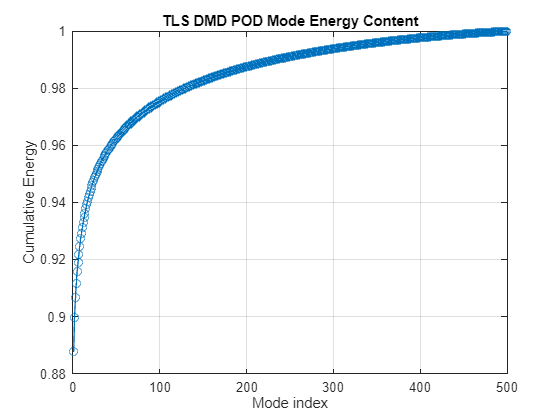


% Determine rank r
sing_vals = diag(Sz);
energy2 = cumsum(sing_vals.^2)/sum(sing_vals.^2);
r = find(energy2 >= 0.99, 1);

figure;
plot(energy, 'o-');
xlabel('Mode index');
ylabel('Cumulative Energy');
title('TLS DMD POD Mode Energy Content');
grid on;

disp(r);

   286



Uz_r = Uz(:,1:r);
Sz_r = Sz(1:r,1:r);
Vz_r = Vz(:,1:r);
disp(size(Uz_r));

      132402         286



n= size(X1,1)

n = 66201

% Split Uz_r back to n x r blocks
U1 = Uz_r(1:n,:);  
U2 = Uz_r(n+1:end,:); 

size(U1)

ans =        66201         286


size(U2)

ans =        66201         286


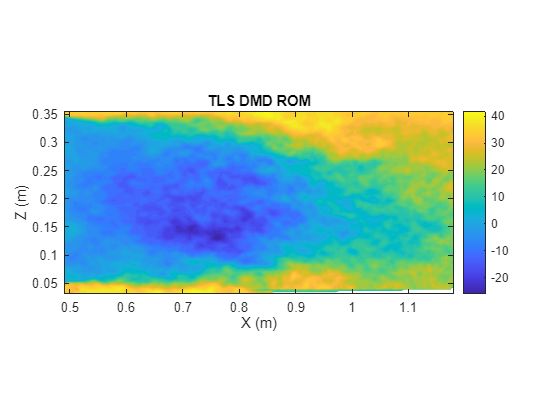

% TLS-DMD operator
A_tilde = U1 \ U2;    

% Eigen decomposition
[W,D] = eig(A_tilde);   
Phi2 = U2 * W;          

% Compute omega
dt = 1;  
omega = log(diag(D))/dt;

% Compute amplitudes
x1 = X1(:,1);
b = Phi2 \ x1;           
b = real(b)
b = b(:);       
omega = omega(:);

% Reconstruct snapshots

timesteps = size(X1,2);
% X_dmd2 = zeros(n,timesteps);
% for i = 1:timesteps
%     X_dmd2(:,i) = real(Phi * (b .* exp(omega*(i-1))));
% end
t = 0:(timesteps-1);        % 1 x timesteps
X_dmd2 = real(Phi2 * (b .* exp(omega * t)));  % outer product

X_dmd2=real(X_dmd2);
Vq2 = griddata(x_slice, z_slice, X_dmd2(:,5), Xq, Zq, 'natural');

%% Plot contour
figure;
contourf(Xq, Zq, Vq2, 40, 'LineStyle', 'none');
colorbar;
xlabel('X (m)');
ylabel('Z (m)');
title('TLS DMD ROM');
axis equal tight;

% Overall Errors 
X_original=X;
size(X_original)

ans =        66201         499


error_mse = mean((X_dmd2(:) - X_original(:)).^2);
error_rel = norm(X_dmd2 - X_original, 'fro') / norm(X_original, 'fro');

fprintf('MSE = %.4e\n', error_mse);

MSE = 5.0025e+01



fprintf('Relative error = %.4f%%\n', error_rel*100);

Relative error = 35.6188%


% Removing any invalid value if present for error calculation
mask_valid = (X ~= -9999) & ~isnan(X); 
error_rel = norm(X_dmd2(mask_valid) - X(mask_valid), 'fro') / ...
            norm(X(mask_valid), 'fro');
fprintf('Relative error (masked) = %.2f%%\n', error_rel*100);

Relative error (masked) = 35.62%


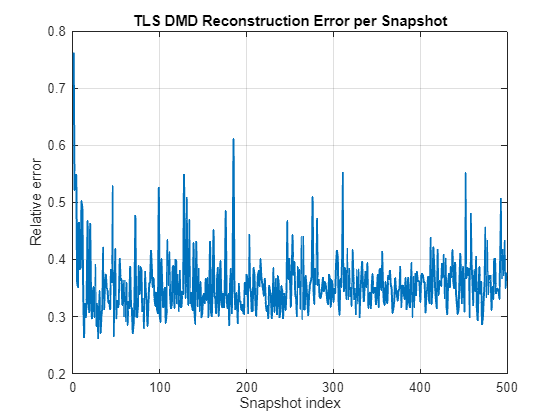

snapshot_error2= vecnorm(X_dmd2 - X_original ) ./ vecnorm(X_original);
figure;
plot(snapshot_error2, 'LineWidth', 1.5);
xlabel('Snapshot index');
ylabel('Relative error');
title('TLS DMD Reconstruction Error per Snapshot');
grid on;

disp("Done")

Done


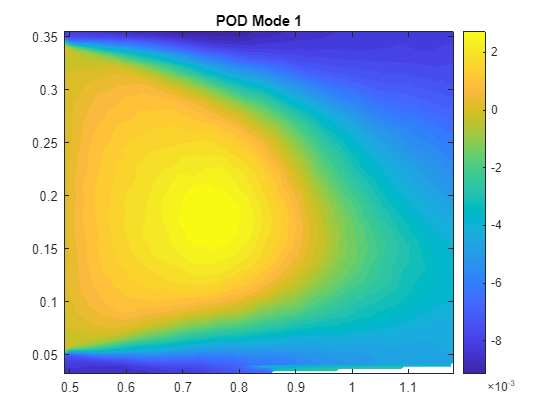

% Analysing POD modes 

mode_index = 1;
phi_pod = U(:, mode_index);
pod = griddata(x_slice, z_slice, phi_pod, Xq, Zq, 'natural');
contourf(xq, zq, pod, 40, 'LineStyle','none');
colorbar;
title(['POD Mode ', num2str(mode_index)]);

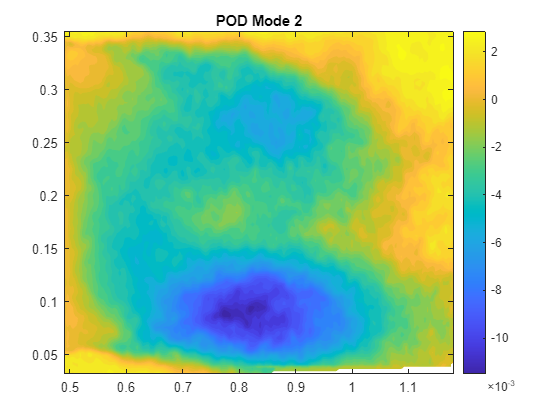


mode_index = 2; 
phi_pod = U(:, mode_index);
pod = griddata(x_slice, z_slice, phi_pod, Xq, Zq, 'natural');
contourf(xq, zq, pod, 40, 'LineStyle','none');
colorbar;
title(['POD Mode ', num2str(mode_index)]);

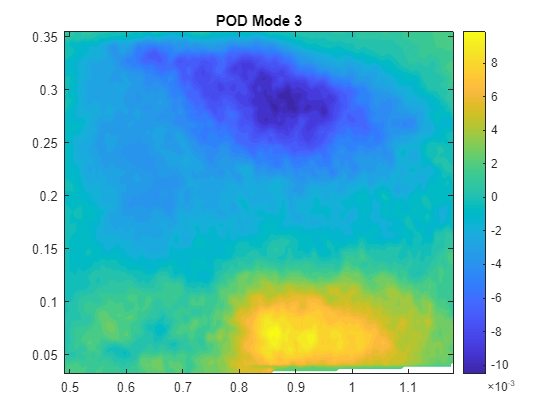


mode_index = 3;
phi_pod = U(:, mode_index);
pod = griddata(x_slice, z_slice, phi_pod, Xq, Zq, 'natural');
contourf(xq, zq, pod, 40, 'LineStyle','none');
colorbar;
title(['POD Mode ', num2str(mode_index)]);

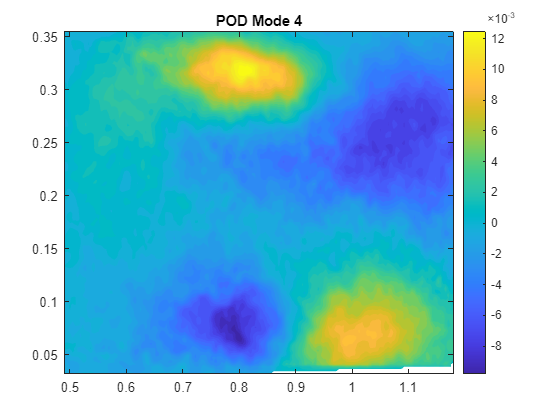

mode_index = 4; 
phi_pod = U(:, mode_index);

pod = griddata(x_slice, z_slice, phi_pod, Xq, Zq, 'natural');
contourf(xq, zq, pod, 40, 'LineStyle','none');
colorbar;
title(['POD Mode ', num2str(mode_index)]);

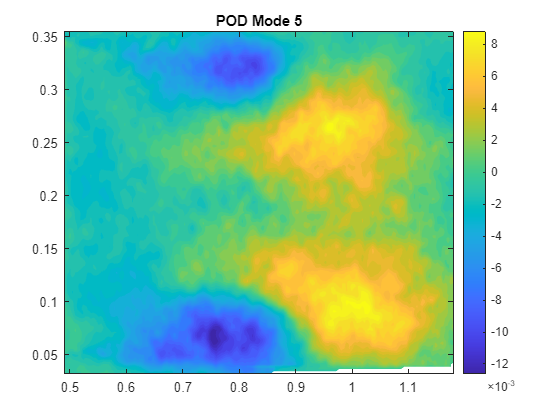

mode_index = 5;
phi_pod = U(:, mode_index);
pod = griddata(x_slice, z_slice, phi_pod, Xq, Zq, 'natural');
contourf(xq, zq, pod, 40, 'LineStyle','none');
colorbar;
title(['POD Mode ', num2str(mode_index)]);

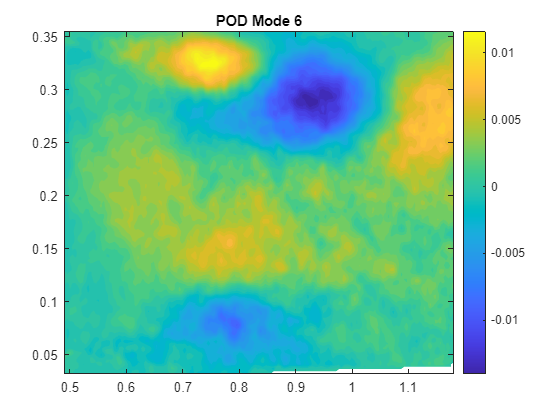


mode_index = 6; 
phi_pod = U(:, mode_index);
pod = griddata(x_slice, z_slice, phi_pod, Xq, Zq, 'natural');
contourf(xq, zq, pod, 40, 'LineStyle','none');
colorbar;
title(['POD Mode ', num2str(mode_index)]);

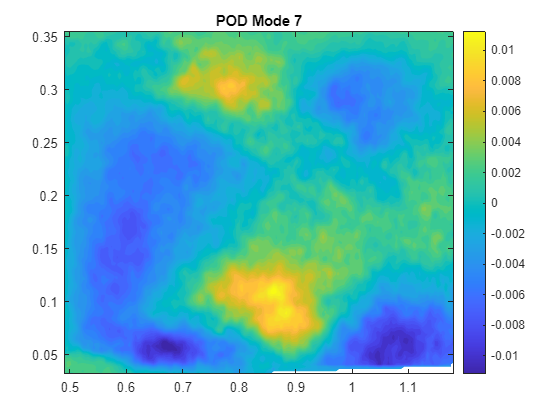

mode_index = 7;
phi_pod = U(:, mode_index);
pod = griddata(x_slice, z_slice, phi_pod, Xq, Zq, 'natural');
contourf(xq, zq, pod, 40, 'LineStyle','none');
colorbar;
title(['POD Mode ', num2str(mode_index)]);

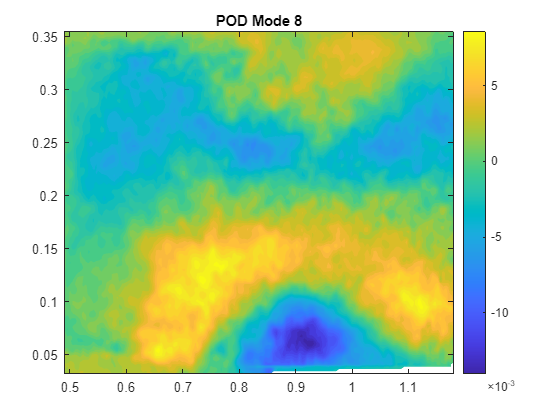

mode_index = 8; 
phi_pod = U(:, mode_index);
pod = griddata(x_slice, z_slice, phi_pod, Xq, Zq, 'natural');
contourf(xq, zq, pod, 40, 'LineStyle','none');
colorbar;
title(['POD Mode ', num2str(mode_index)]);

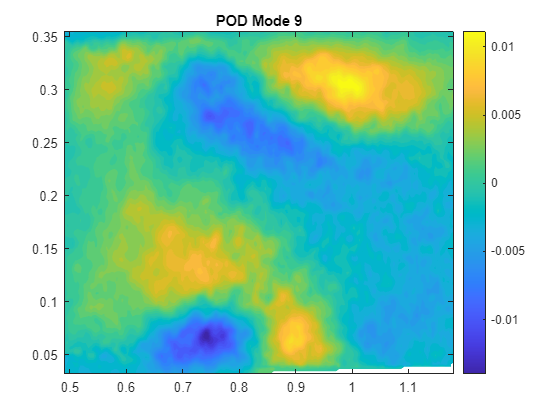

mode_index = 9; 
phi_pod = U(:, mode_index);
pod = griddata(x_slice, z_slice, phi_pod, Xq, Zq, 'natural');
contourf(xq, zq, pod, 40, 'LineStyle','none');
colorbar;
title(['POD Mode ', num2str(mode_index)]);

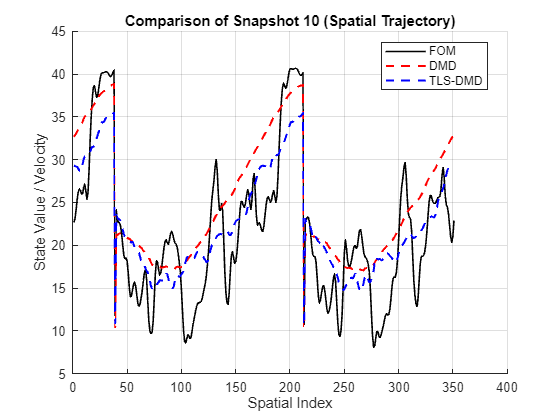

% Trajectory comparison 

figure;
hold on;
plot(X(1700:2050,10), 'k-', 'LineWidth', 1.2, 'DisplayName', 'FOM');        % original snapshot
plot(X_dmd(1700:2050,10), 'r--', 'LineWidth', 1.5, 'DisplayName', 'DMD');     % standard DMD
plot(X_dmd2(1700:2050,10), 'b--', 'LineWidth', 1.5, 'DisplayName', 'TLS-DMD'); % TLS-DMD

xlabel('Spatial Index');
ylabel('State Value / Velocity');
title('Comparison of Snapshot 10 (Spatial Trajectory)');
legend('Location', 'best');
grid on;